# Unsupervised Learning In-Class Practice: Answer Key

## Loading and examining the data

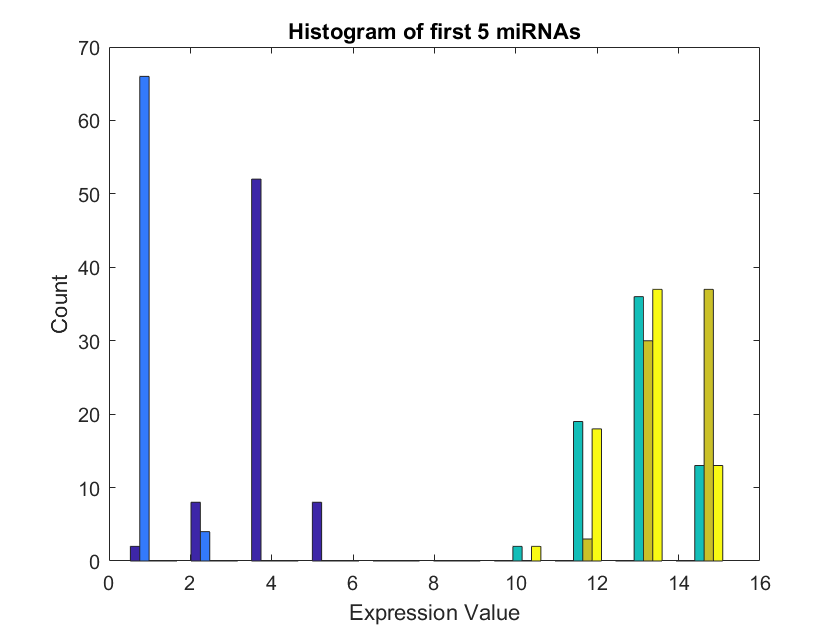

% Load the dataset
miRNA = readtable('miRNA_data.xlsx');
% Create a variable for patient IDs
patient_ID = miRNA.Patient_ID;
% Create a variable for patient health status
health_stat = miRNA.Health_Status; 
% Create a variable for miRNA names
miRNA_names = miRNA.Properties.VariableNames(3:end);
% Create a variable for miRNA expression data
miRNA_data = table2array(miRNA(:,3:end));

% Histogram of miRNA expression data
hist(miRNA_data(:,1:5))
xlabel('Expression Value'); ylabel('Count')
title('Histogram of first 5 miRNAs')

Answer: The expression level for two miRNAs is much lower that the other three. In other words, the expression level for different miRNAs within this dataset may be drastically different. 

## Determining optimal k value using KMC

% Demo for k-means clustering                                 
idx = kmeans(miRNA_data,2);             % identify clusters with k-means clustering
s = silhouette(miRNA_data,idx);         % determine silhouette values 
s_score = mean(s)                       % calculate silhouette score 

s_score = 0.5539

% Create a vector of k values ranging from 2 to 10
k_values = 2:10;

% For-loop to calculate the silhouette statistic for different k values
n = length(k_values);       % number of k values
s_score = zeros(n,1);       % variable to store silhouette statistic values
for i = 1:n
    % Use the kmeans function to cluster patients into k clusters
    [idx,~] = kmeans(miRNA_data,k_values(i));
    % Use the silhouette function to determine silhouette values
    s = silhouette(miRNA_data,idx);
    % Calculate the silhouette score by taking the mean
    s_score(i) = mean(s);
end
max(s_score)

ans = 0.5539

k = find(s_score==max(s_score))+1

k = 2

Answer: The max silhouette statistic is equal to 0.5539, and this corresponds with k = 2.

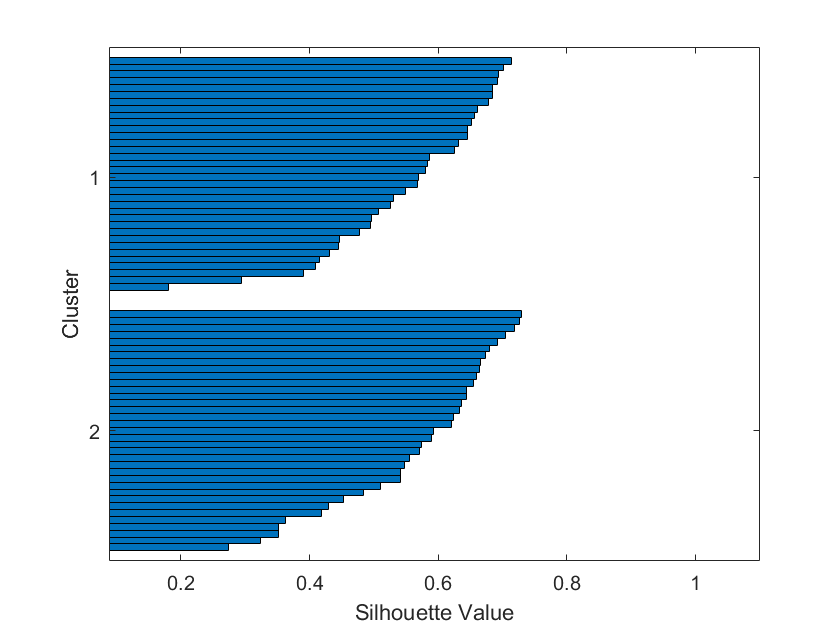

% Silhouette plot based on best k value
[idx,~] = kmeans(miRNA_data,k);
silhouette(miRNA_data,idx)

Answer: No negative values are present, but a negative silhouette value would imply that its associated observation was not well-placed into its assigned cluster. 

cluster_1 = health_stat(idx == 1)

cluster_1 = 35×1 cell array
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'diseased'}
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }

cluster_2 = health_stat(idx == 2)

cluster_2 = 35×1 cell array
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}

Answer: The patients cluster based on health status (for the most part).

## Visualizing data in lower dimension using PCA

% Visualize miRNA data in component space (use patient health status for labeling)
mapcaplot(miRNA_data,health_stat)

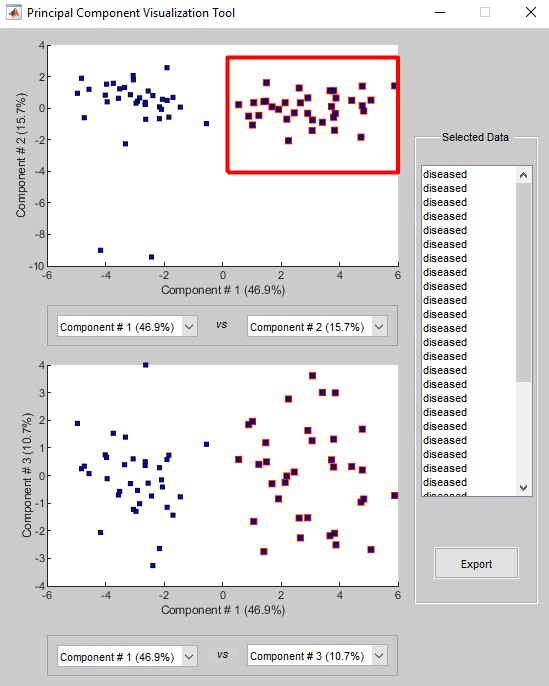

Answer: There seems to be two distinct clusters with two outliers. PC1 and PC2 account for 62.6% of the variance.

Answer: Yes, it seems like the clusters we see from PCA match with our results from k-means clustering.

% Determine coefficient matrix using PCA
[coeff,scores] = pca(miRNA_data); 
% Create table of genes matched to coefficients of best PC
pc1_coeff = coeff(:,1); 
table(miRNA_names',pc1_coeff)

ans = 18×2 table
          Var1          pc1_coeff
    ________________    _________
    {'hsa_let_7f_1'}     0.030013
    {'hsa_mir_122' }     0.023985
    {'hsa_let_7a_1'}     -0.25779
    {'hsa_let_7a_2'}     -0.25868
    {'hsa_let_7a_3'}     -0.25639
    {'hsa_let_7b'  }     -0.14155
    {'hsa_let_7c'  }     -0.30004
    {'hsa_let_7d'  }    0.0069857
    {'hsa_let_7e'  }     -0.22136
    {'hsa_let_7f_2'}     -0.28449
    {'hsa_let_7g'  }    0.0058268
    {'hsa_let_7i'  }     0.078598
    {'hsa_mir_10b' }      0.10396
    {'hsa_mir_145' }    -0.085872
    {'hsa_mir_155' }      0.29161
    {'hsa_mir_21'  }      0.35256

Answer: miRNA 33a has the greatest weight (0.4131) for PC1.

## Identifying differentially expressed miRNAs using HC

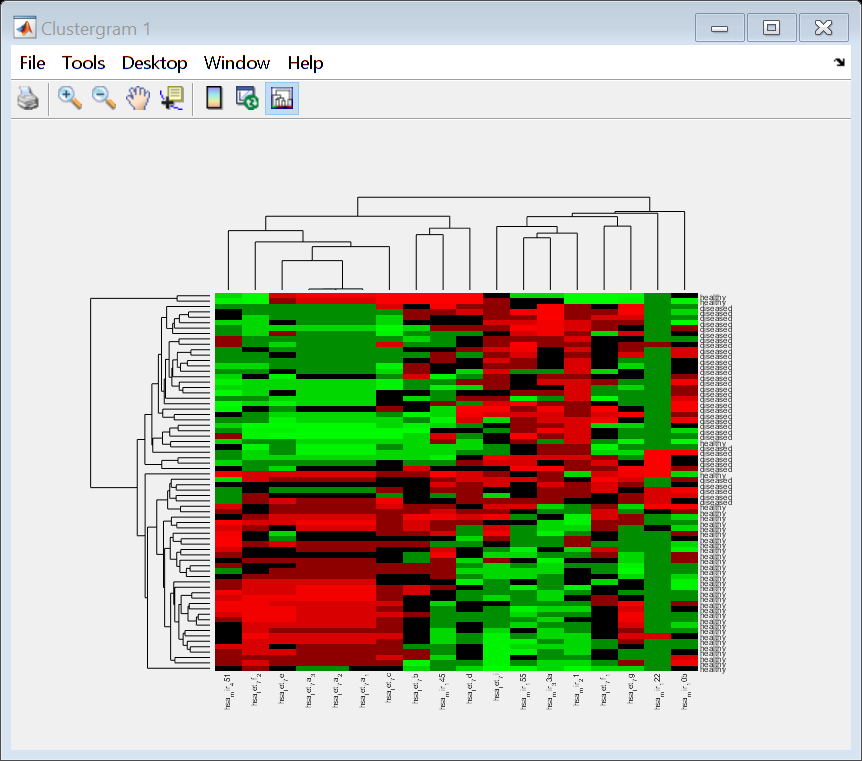

% Create clustergram (label rows, label columns, and standardize by
% columns)
miRNA_cg = clustergram(miRNA_data,...
    'RowLabels',health_stat,...
    'ColumnLabels',miRNA_names,...
    'Standardize','column');

Answer: It seems that the outliers were picked out at the edges, but the two clusters we've seen before are not clearly separated. 

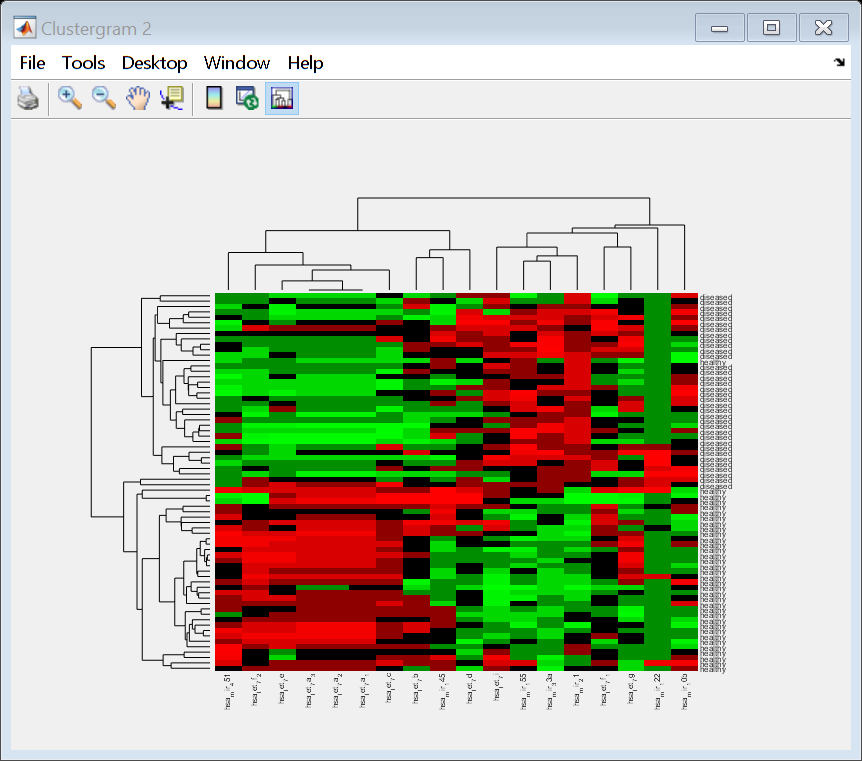

% Clustergram with redbluecmap
miRNA_cg_corr_rbc = clustergram(miRNA_data,...
    'RowLabels',health_stat,...
    'ColumnLabels',miRNA_names,...
    'Standardize','column',...
    'RowPDist','correlation',...
    'ColumnPDist','correlation');

Answer: As opposed to before, this clustergram better separates patients according to their health status. This matches closer to our previous results from KMC and PCA. 

Answer: Based on the clustergram, the following miRNAs appear to be differentially expressed between healthy and diseased individuals: miR-451, *Let*-7, miR-155, miR-33, and miR-21. 